## Motorized Bar Mechanism  

We created a rigid linkage mechanism with 4 bars and a slider cranck. L20 is a 0.2 m long link with a radius of 0.03 m. Links L50 and L70 are longer variations of the same link.

All links have a revolute joint attached at the base and the linkage has 2 closed-loop joints. A revolute joint closes the top loop (4 bar mechanism) while a prismatic joint forms the slider in the lower loop (slider-crank mechanism). The revolute joint attached to  `L20 `is actuated and controlled by input angles.

SorosimLinks (`L20, L50 and L70`) and SorosimLinkage (M) are saved in `4Bar&SliderCranck.mat`

load('4Bar&SliderCrank.mat')

To see the properties of `L20`

L20

To see the properties of L50

L50

To see the properties of L70

L70

To see the properties of M

M

To see the problem definition:

M.plotq0

The result should be:

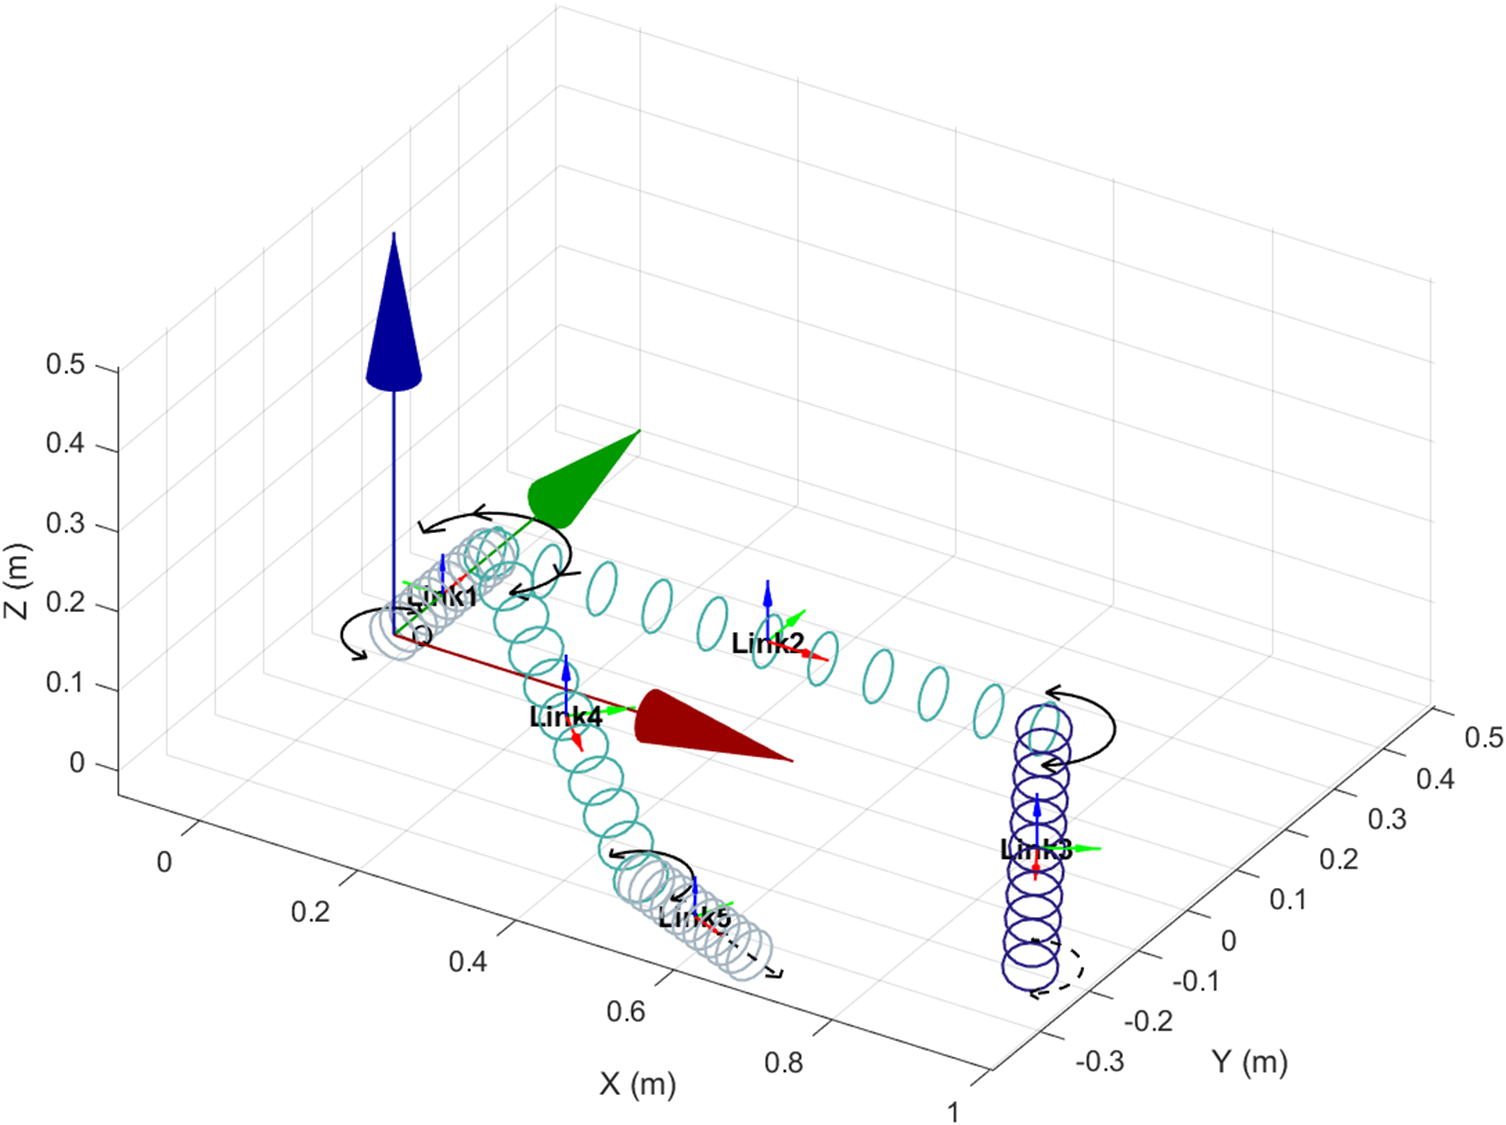

The revolute joint of link 1 is actuated by the value of the joint angle.

### **Dynamic Analysis**

For dynamics problem, type:

[t,qqd]=M.dynamics;

The user can enter the angle of the actuated revolute joint as a function of time to simulate the motion of the mechanism in time (eg: pi*t) . Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.